# **EJERCICIO 02**

G1 = tf([1],[1 1])

G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




G2 = tf([1],[1 2])

G2 =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.



**Definición de los parámetros de los diferentes controladores**

%Controlador P
Kp = 2.35

Kp = 2.3500

P = tf(Kp,1)

P =
 
  2.35
 
Static gain.




%Controlador PI
KI = 0.235

KI = 0.2350

Ti = 0.1

Ti = 0.1000

PI = zpk([-1/Ti],[0],KI)

PI =
 
  0.235 (s+10)
  ------------
       s
 
Continuous-time zero/pole/gain model.




%Controlador PID
KID = 2.55

KID = 2.5500

TID = 1.28

TID = 1.2800

TD = 0.09

TD = 0.0900

PID = tf([KID*TD*TID KID*TID KID],[TID 0])

PID =
 
  0.2938 s^2 + 3.264 s + 2.55
  ---------------------------
            1.28 s
 
Continuous-time transfer function.



**Respuesta del sistema ante una entrada escalon**

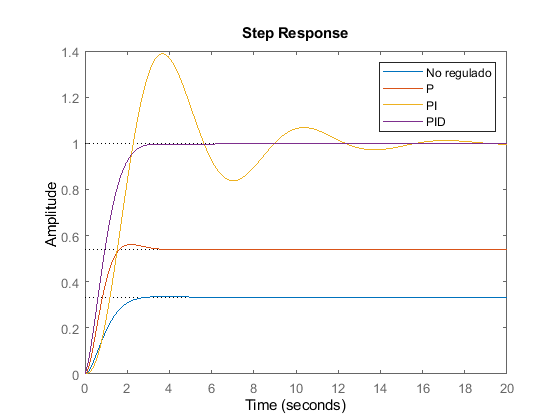

%Respuestas
figure; hold on; title('Respuesta escalón')
step(feedback(G1*G2,1),20)
step(feedback(P*G1*G2,1),20)
step(feedback(PI*G1*G2,1),20)
step(feedback(PID*G1*G2,1),20)
legend('No regulado','P','PI','PID')

**Representación de los polos en lazo cerrado**

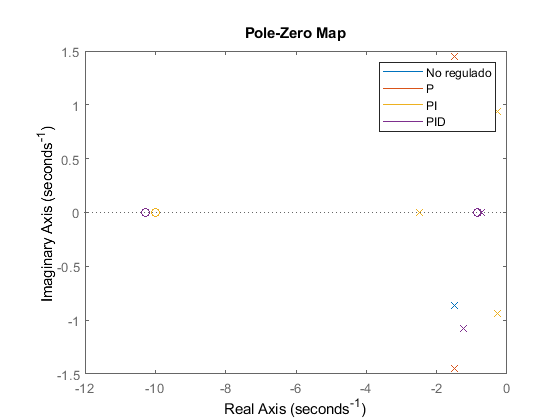

% Polos LC
figure; hold on; title('Respuesta escalón')
pzmap(feedback(G1*G2,1))
pzmap(feedback(P*G1*G2,1))
pzmap(feedback(PI*G1*G2,1))
pzmap(feedback(PID*G1*G2,1))
legend('No regulado','P','PI','PID')

**Evolución de la salida cuando se añade una perturbacion**

t = 0:0.1:50;
x1 = ones(size(t))

x1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


x2 = x1; x2(1:200) = 0;
%Respuesta anulando la perturbacion + respuesta anulando la entrada
y1 = lsim(feedback(G1*G2,1),x1,t) + lsim(feedback(G1*G2,1),x2,t)

y1 =          0
    0.0045
    0.0164
    0.0334
    0.0537
    0.0760
    0.0991
    0.1224
    0.1450
    0.1667


y2 = lsim(feedback(P*G1*G2,1),x1,t) + lsim(feedback(G1*G2,P),x2,t)

y2 =          0
    0.0106
    0.0383
    0.0776
    0.1241
    0.1741
    0.2248
    0.2742
    0.3208
    0.3635


y3 = lsim(feedback(PI*G1*G2,1),x1,t) + lsim(feedback(G1*G2,PI),x2,t)

y3 =     0.0000
    0.0014
    0.0066
    0.0164
    0.0314
    0.0521
    0.0784
    0.1103
    0.1476
    0.1900


y4 = lsim(feedback(PID*G1*G2,1),x1,t) + lsim(feedback(G1*G2,PID),x2,t)

y4 =          0
    0.0312
    0.0760
    0.1305
    0.1915
    0.2562
    0.3223
    0.3883
    0.4525
    0.5140


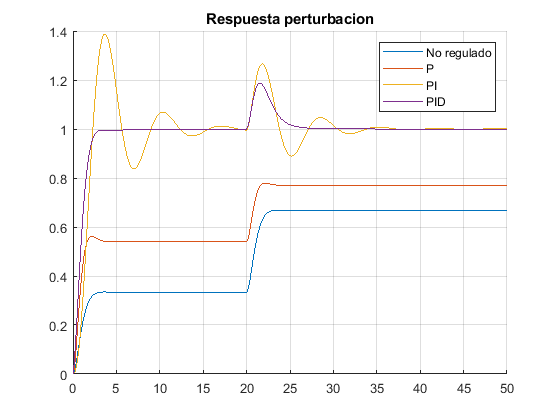

%grid on es para sacar una cuadricula
figure; hold on; grid on; title('Respuesta perturbacion')
%Hace falta poner t para cada respuesta que representemos
plot(t,y1,t,y2,t,y3,t,y4)
%El PI y el PID rechazan la perturbacion por el polo que tienen en la realimentacion
legend('No regulado','P','PI','PID')

# Ejercicio 03

%Creamos la FDT del ejercicio 3
G3 = tf([1], [1 2])

G3 =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.



# Ejercicio 04

G4 = tf([8],[1 5])

G4 =
 
    8
  -----
  s + 5
 
Continuous-time transfer function.



# Ejercicio 05

G5 = tf([4],[1 0 -2])

G5 =
 
     4
  -------
  s^2 - 2
 
Continuous-time transfer function.



# Ejercicio 06

G6 = tf([1.2],[2.56 1])

G6 =
 
     1.2
  ----------
  2.56 s + 1
 
Continuous-time transfer function.



G7 = zpk([],[-0.3 -0.1],0.1)

G7 =
 
        0.1
  ---------------
  (s+0.3) (s+0.1)
 
Continuous-time zero/pole/gain model.



%Como sisotool no coge dos variables, guardamos la FDT en una unica
%variable
G8 = G6*G7

G8 =
 
           0.046875
  --------------------------
  (s+0.3906) (s+0.3) (s+0.1)
 
Continuous-time zero/pole/gain model.

